### Задание 2С

N = 1000;
m = 0:N-1;
R_y = 1./(m+1);
a = -(N-1):(N-1)

a =   -999  -998  -997  -996  -995  -994  -993  -992  -991  -990  -989  -988  -987  -986  -985  -984  -983  -982  -981  -980  -979  -978  -977  -976  -975  -974  -973  -972  -971  -970  -969  -968  -967  -966  -965  -964  -963  -962  -961  -960  -959  -958  -957  -956  -955  -954  -953  -952  -951  -950


stem(-(N):(N), [flip(R_y) R_y]), title("АКФ"), xlabel("m"), ylabel(".")

Error using stem (line 102)
X must be same length as Y.

x_1 = fft(R_y);

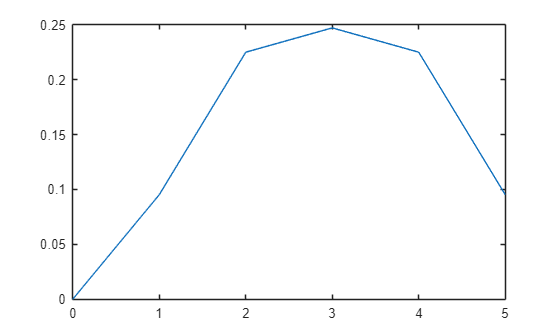

F = [0 0.2 0.25 0.35 0.4 1]; A = [0 0 1 1 0 0];
b = fir2(5, F, A);
B = abs(fftshift(fft(b)));
plot(0:5, B)